# Ejercicio del libro modelos fisicos

## 3. Modelado matemático de sistemas físicos

3.1 De acuerdo con el principio de Arquímedes, la fuerza de flotación es igual al peso de fluido desplazado por la porción sumergida de un objeto. Para el tronco de un cono, determina la altura $h_1$ de la porción que queda encima del agua. 

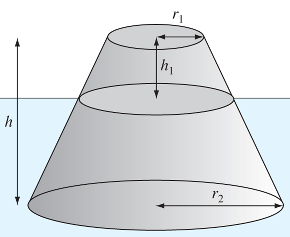

El volumen del tronco está dado por:


$$V=\frac{\pi h}{3}\left({r_1 }^2 +{r_2 }^2 +r_1 r_2 \right)$$


Sea r el radio a la altura de la superficie del agua. Por triángulos semejantes se sabe que:


$$\frac{r-r_1 }{h_1 }=\frac{r_2 -r_1 }{h}$$



$$r=r_1 +\frac{r_2 -r_1 }{h}h_1$$


Usa los siguientes valores para el cálculo;

r1 = 0.5;           % m
r2 = 1;
h = 1;
rhoF = 200;         % densidad del cono kg/m^3
rhoA = 1000;        % densidad del agua
volTronco= (((pi*h)/3)*(r1^2+r2^2+r1*r2))*(rhoA-rhoF);

volTronco =      1.466076571675237e+03


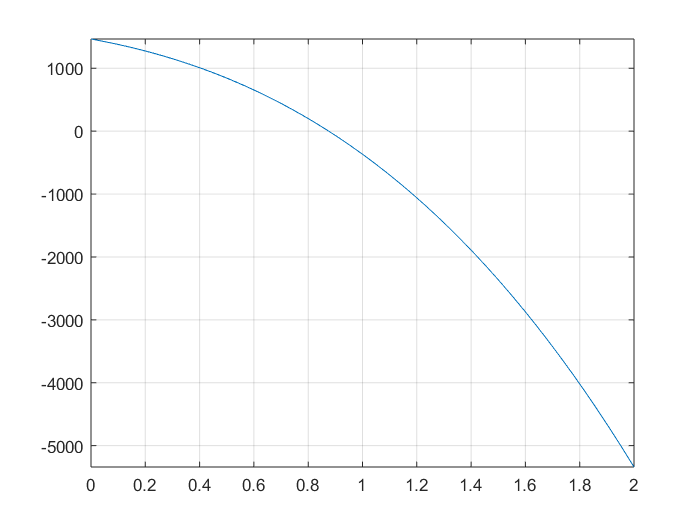

auxRadio = (r2-r1)/h;
%f = @(h1) volTronco - (((pi.*h1)/3).*((r1+((r2-r1)/h).*h1)).^2).*rhoA;
f = @(h1) volTronco - (((pi.*h1)/3).*(r1.^2 + (r1 + ((r2-r1)/h).*h1).^2 + r1.*(r1+((r2-r1)/h).*h1)))*rhoA;
int = [0,2*r2];
fplot(f, int);
grid on;


[x,i] = biseccion(f,0.8,1.0)

x =    0.875777455366903


i =     50
